# ECE1150 ASSIGNMENT2 YINHAO QIAN

%please ignore this block
answer = @(num,unit) fprintf(" ANSWER: %f [%s] \n",num,unit);
question = @() eval("clearvars -except answer question");

# Q1_A

question();
lambda = 1;%[packets/s] average arrival rate
mu = 1.5;%[packets/s] average service rate
D = 1/(mu-lambda);%[s] average delay 
W = D-1/mu;%[s] average waiting time
answer(W,"s");

 ANSWER: 1.333333 [s] 


serviceTime = 1/mu;%[s] average service time
answer(serviceTime,"s");

 ANSWER: 0.666667 [s] 


# Q1_B

Please refer to ./assi2_subm/assi2_q1b_simu.slx for source code infomation:

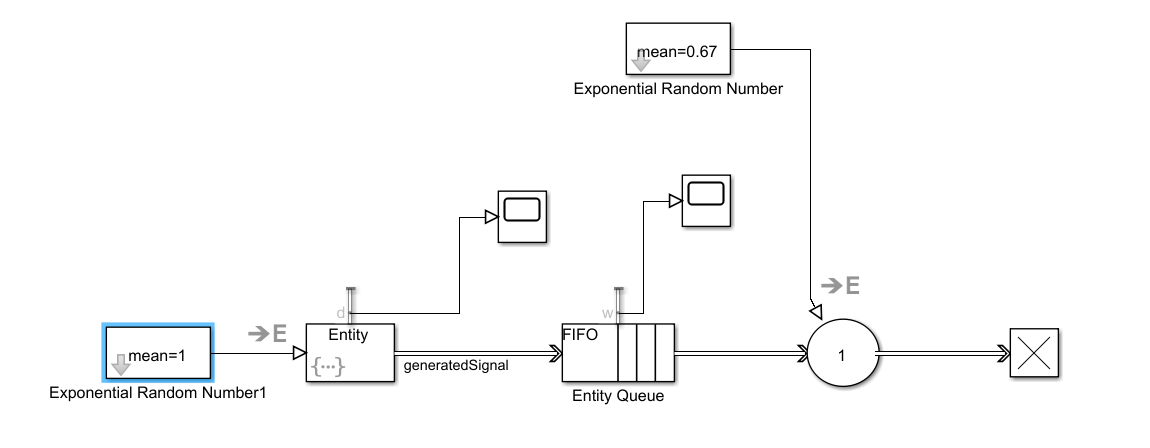

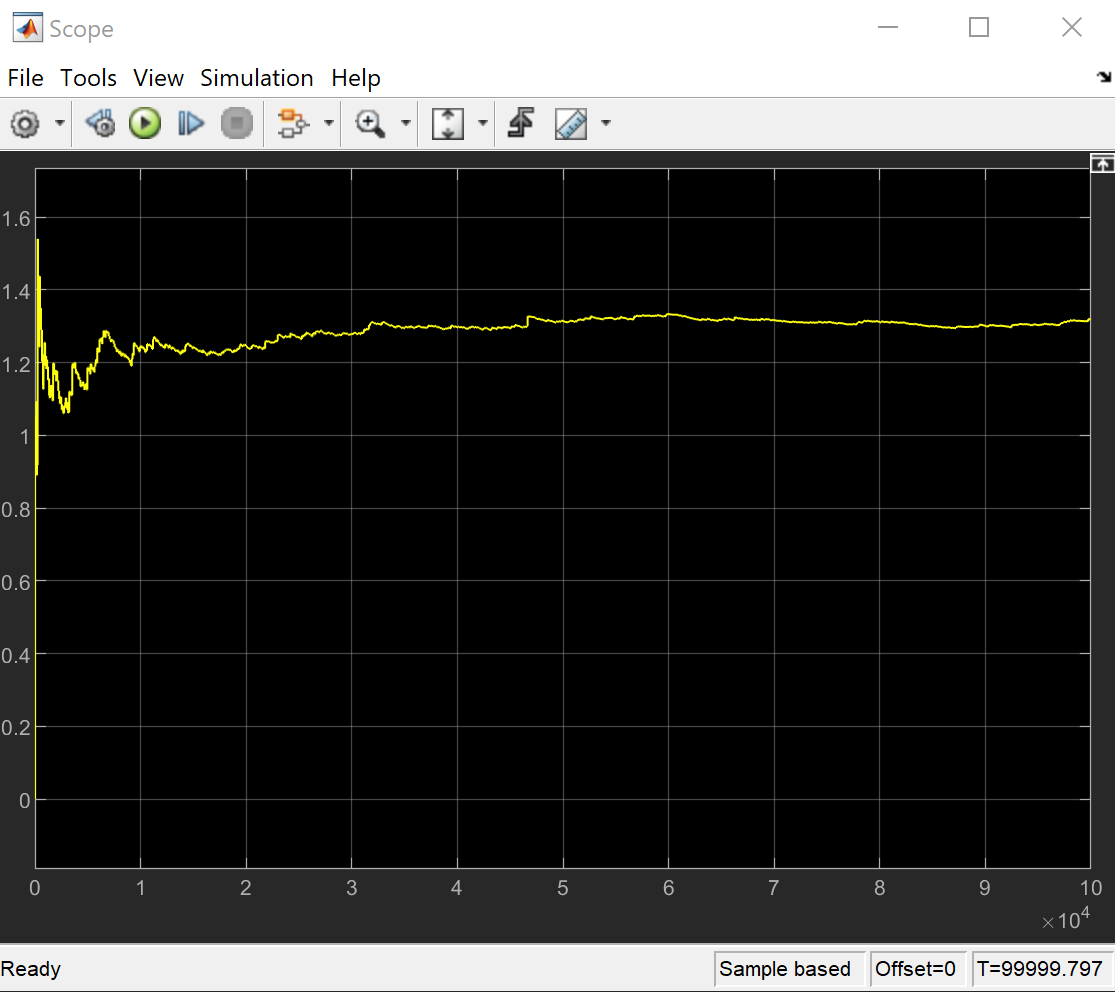

We can tell that the average waiting time is around 1.3333 [s], which matches with our calculation.

# Q1_C

## Stable Case:

Let's try another stable case with average arrival rate halved, which means the average arrival time doubled:

question();
lambda = 0.5;%[packets/s] average arrival rate
mu = 1.5;%[packets/s] average service rate
D = 1/(mu-lambda);%[s] average delay 
W = D-1/mu;%[s] average waiting time
answer(W,"s");

 ANSWER: 0.333333 [s] 


serviceTime = 1/mu;%[s] average service time
answer(serviceTime,"s");

 ANSWER: 0.666667 [s] 


Please refer to ./assi2_subm/assi2_q1c1_simu.slx for source code infomation:

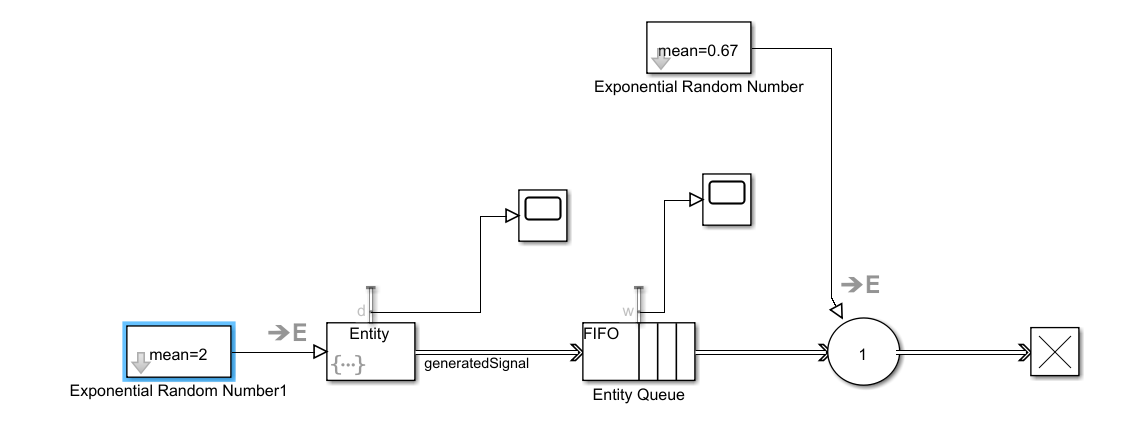

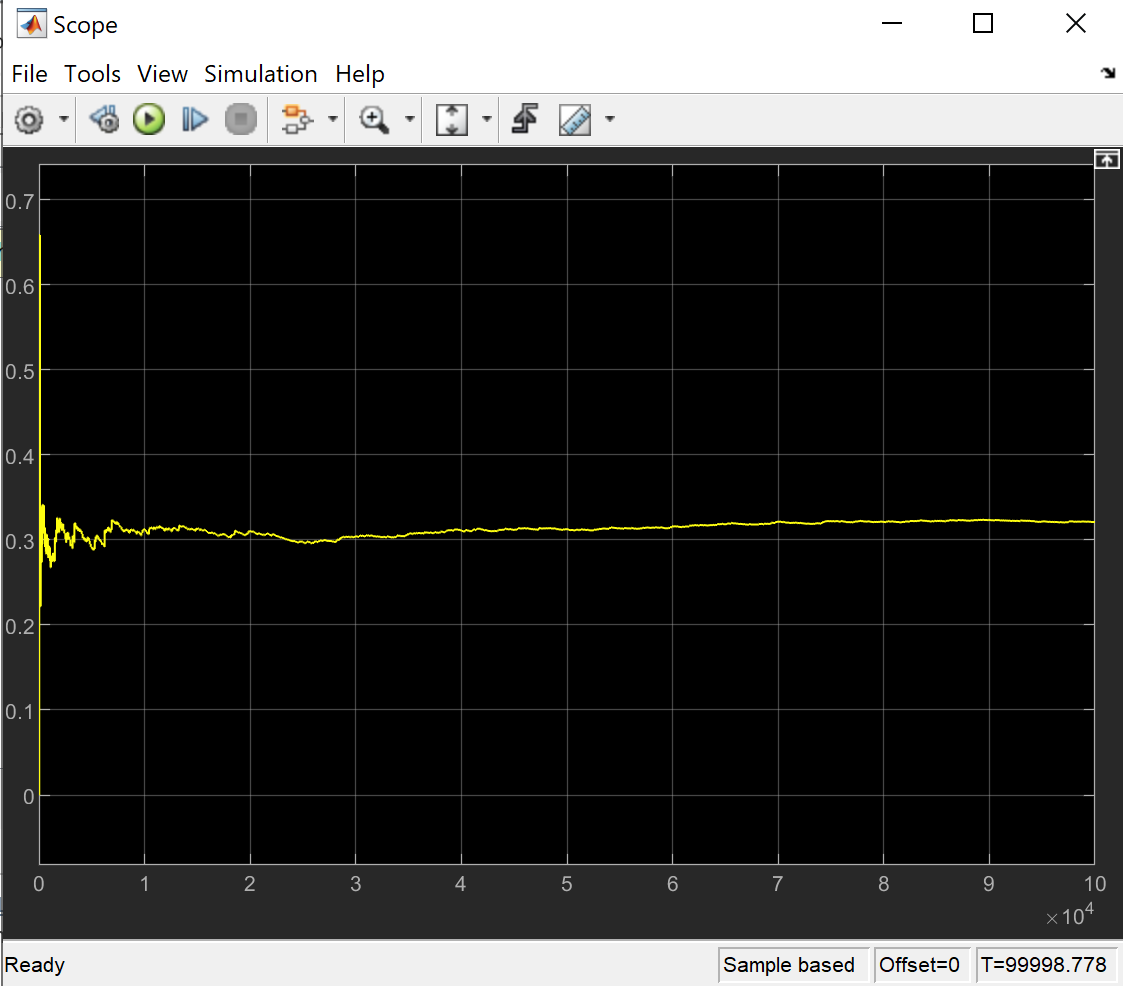

We can tell that the average waiting time is around 0.3333 [s], which matches with our calculation.

## Unstable Case:

Let's make the average service rate very low, and now it takes 10 secs on average to merely serve one packet:

question();
lambda = 1;%[packets/s] average arrival rate
mu = 0.1;%[packets/s] average service rate
D = 1/(mu-lambda);%[s] average delay 
W = D-1/mu;%[s] average waiting time
answer(W,"s");

 ANSWER: -11.111111 [s] 


serviceTime = 1/mu;%[s] average service time
answer(serviceTime,"s");

 ANSWER: 10.000000 [s] 


Please refer to ./assi2_subm/assi2_q1c2_simu.slx for source code infomation:

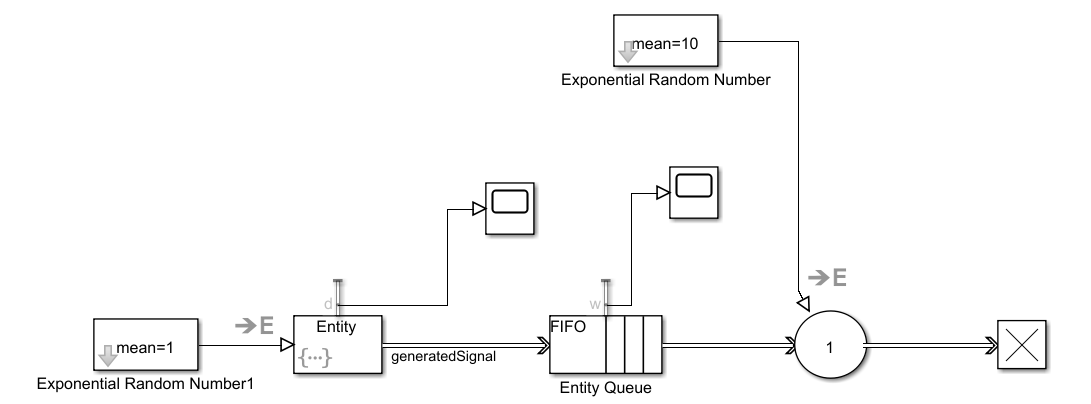

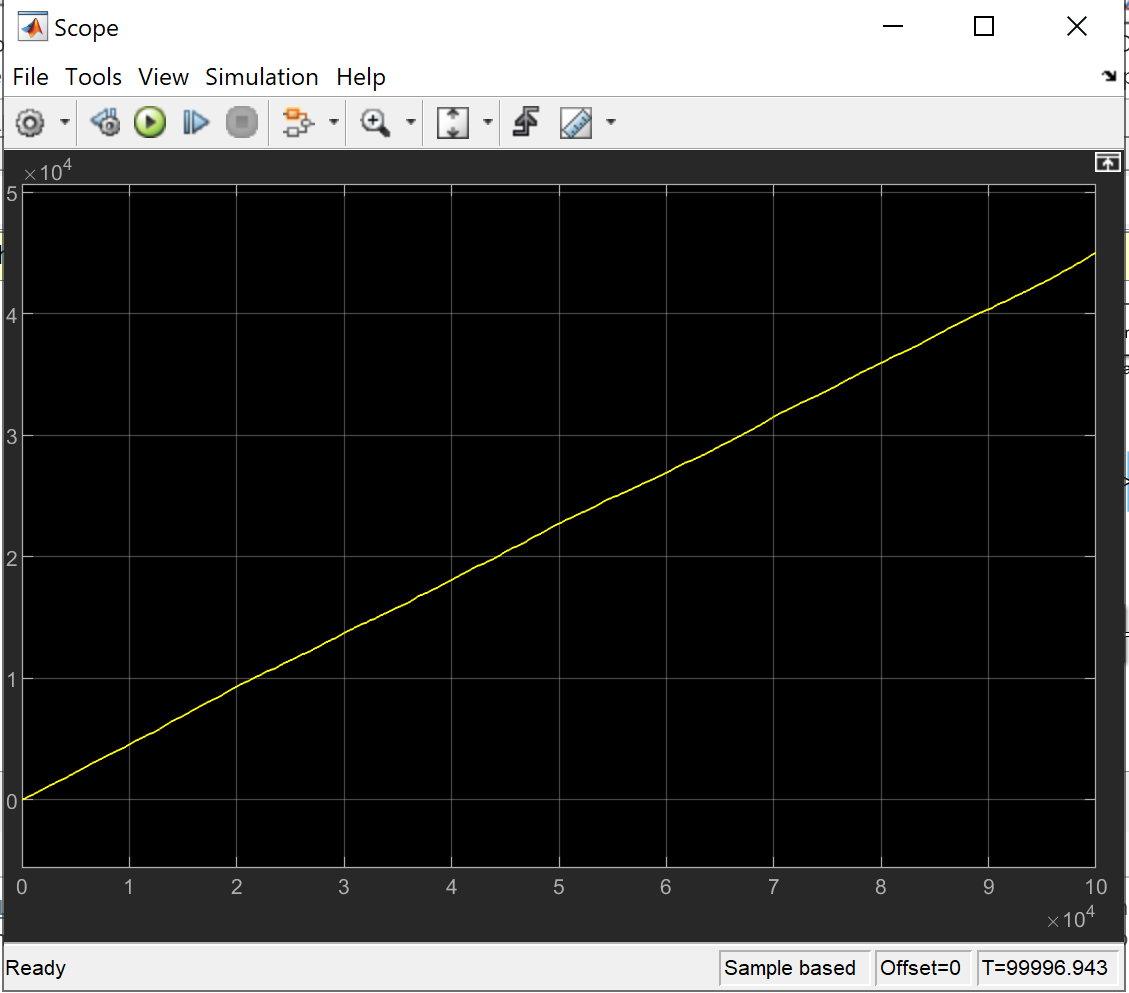

We can observe the analytical calculation is unable to give us a realistic answer, because the average waiting time being unstable makes the overflow of quene, yet we have set our capacity to be infinite. Now let's see what will happen if a capacity limit is placed:

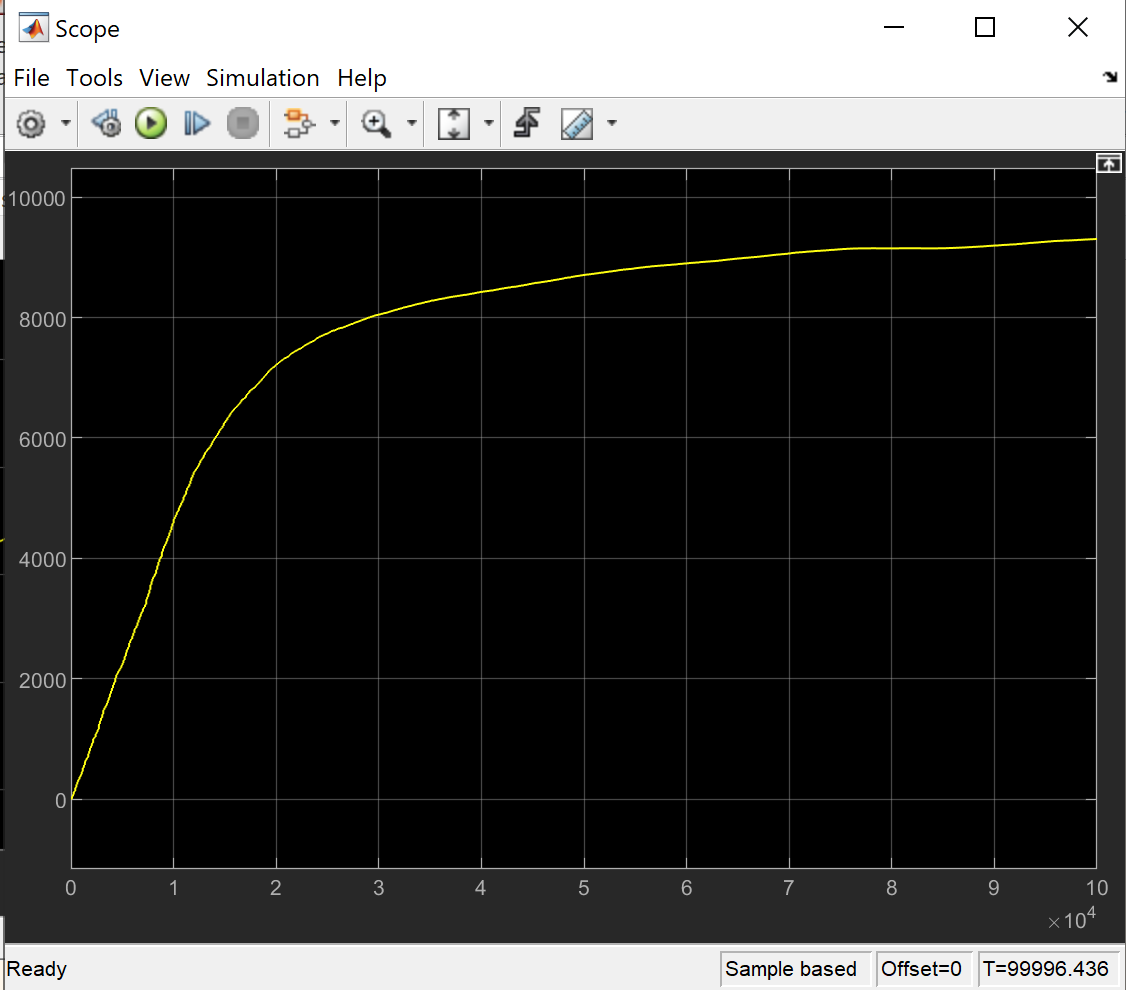

# Q3

## Analytical Estimation:

lambda = [9,3,4];%[packets/s] average arrival rate for each channel
mu = [14,12];%[packets/s] average service rate for each queue
p = 1/4;%[] splitting rate
lambda = [p*(lambda(1)+lambda(2))+lambda(3),(1-p)*(lambda(1)+lambda(2))];
D = 1./(mu-lambda);%[s] average delay 
W = D-1./mu;%[s] average waiting time
answer(W(1),"s");%[s] average service time for queue A
answer(W(1),"s");%[s] average wait time for queue A

 ANSWER: 0.071429 [s] 


answer(1/mu,"s");%[s] average service time for queue B
answer(1/mu,"s");%[s] average wait time for queue B

 ANSWER: 0.250000 [s] 


## Simulink Estimation:

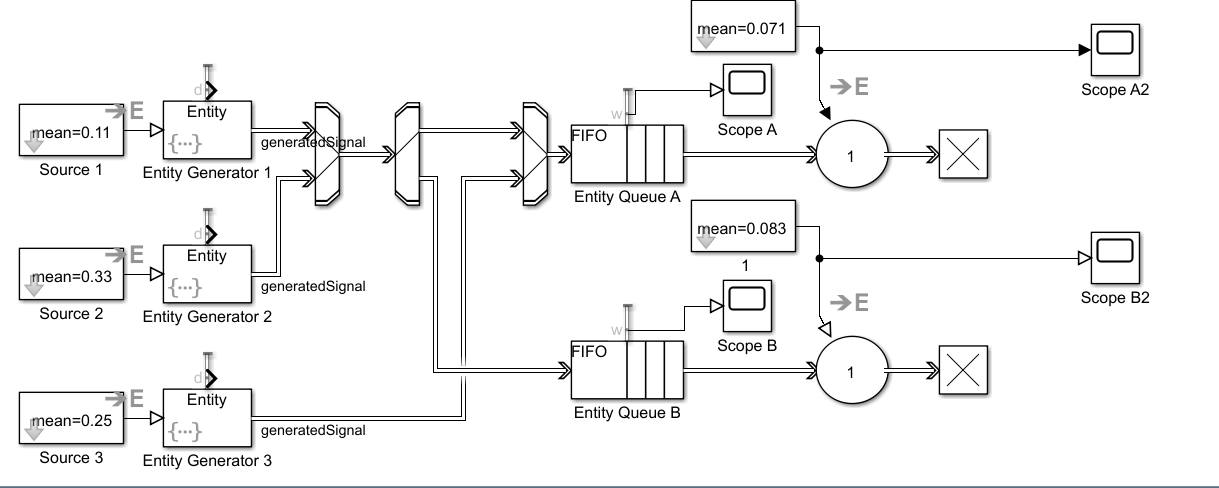

### Wait time:

For Queue A:

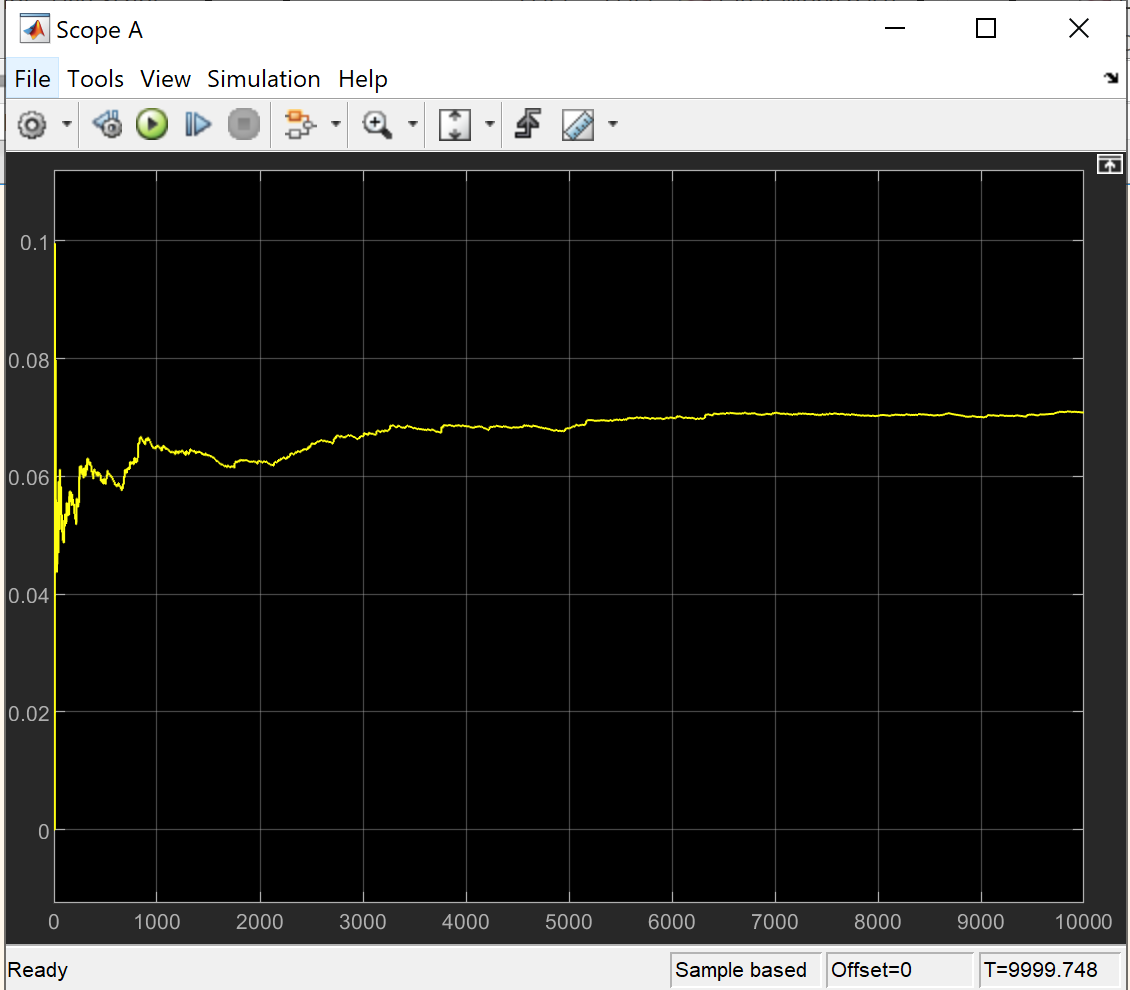

For Queue B:

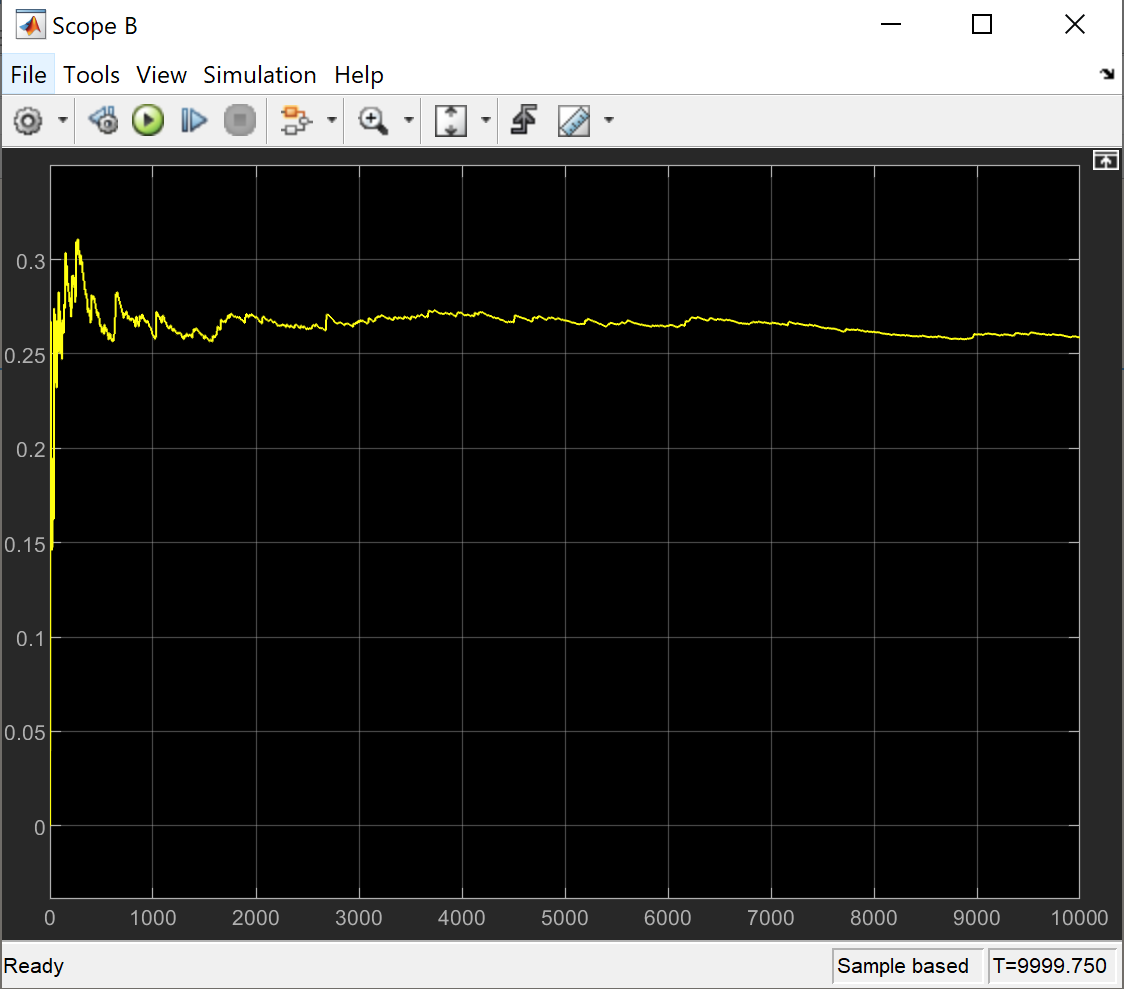

### Service Rate (Used to conclude Average Service Time):

For Queue A:

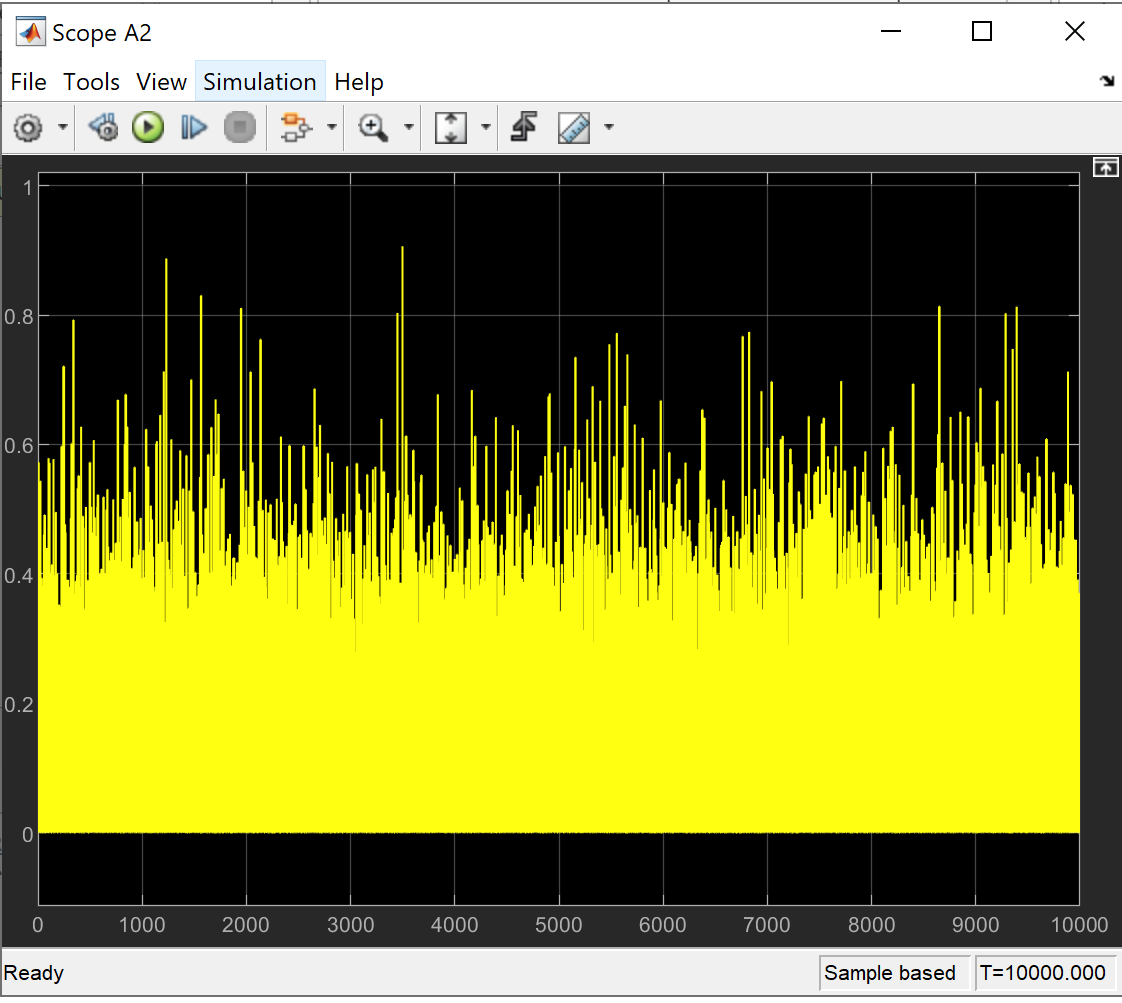

For Queue B:

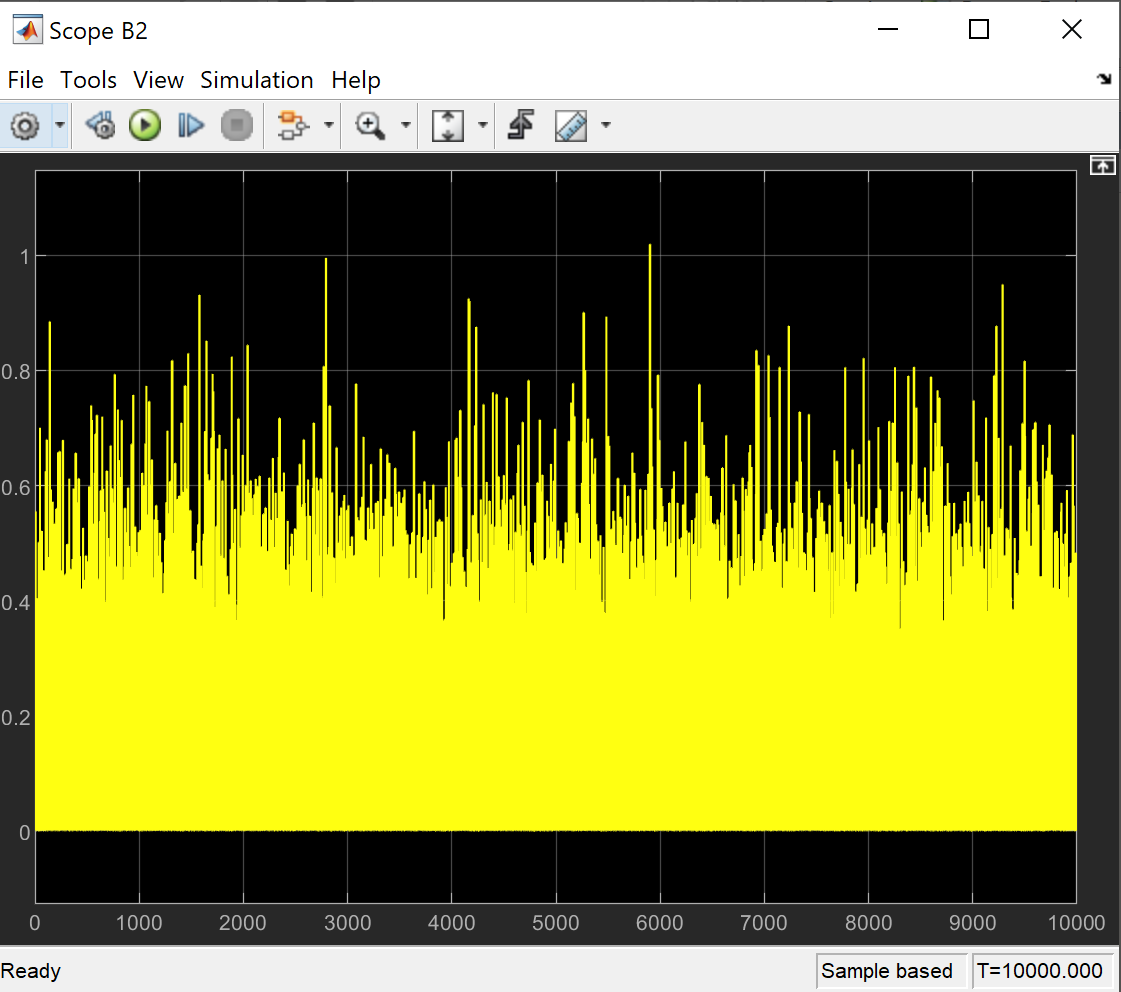

To observe the average serving time, simply take the reciprocal of the average serving rate.